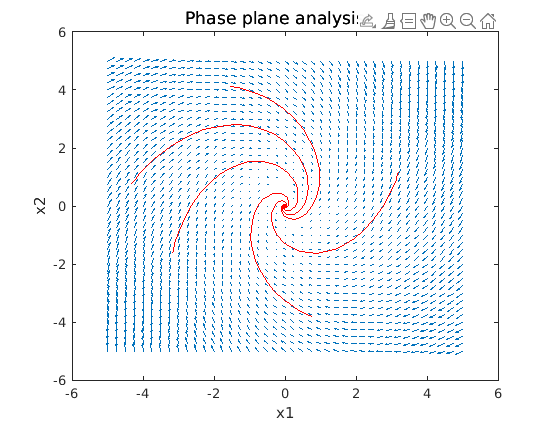

x0 =    -1.5352    4.1207


x0 =     3.1972    1.1552


x0 =     0.7465   -3.8103


x0 =    -4.3239    0.7759


x0 =    -3.1690   -1.6034


clc;
clear;
[x1,x2]=meshgrid(-5:0.25:5,-5:0.25:5);
eps=1;
dx1=-eps*x1+x2;
dx2=-2*x1-eps*x2;
figure;
quiver(x1,x2,dx1,dx2);
sgtitle('Phase plane analysis')
xlabel('x1')
ylabel('x2')
hold on
for i=1:5
    x0=ginput(1)
    tspan=[0,300];
    [t,x]=ode45(@(t,x) odefun1(x),tspan,x0);
    plot(x(:,1),x(:,2),'r')
end

The system above can be written in matrix form. **To find:-**eigen values and equilibrium point

A1=[-eps,1;-2,-eps];
eq_pt1=null(A1)

eq_pt1 =
  2×0 empty double matrix


e1=eig(A1)

e1 =   -1.0000 + 1.4142i
  -1.0000 - 1.4142i


Clearly the eigen values are complex with negative real part and hence it is a **stable focus**.

The null space is empty which means that the only equilibrium point is **origin**.

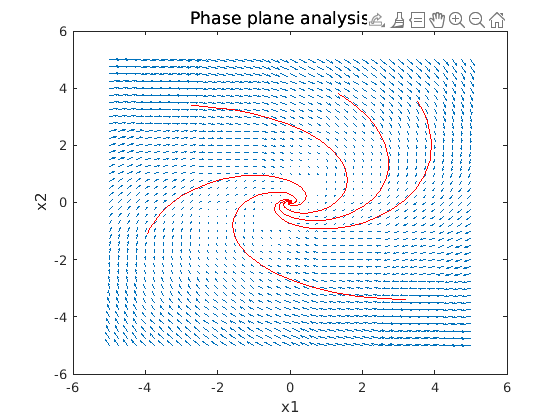

x0 =     3.5253    3.5335


x0 =     3.1935   -3.3936


x0 =    -3.9401   -1.0845


x0 =    -2.7235    3.3936


x0 =     1.3410    3.8134


clc;
clear;
[x1,x2]=meshgrid(-5:0.25:5,-5:0.25:5);
eps=1;
dx1=-eps*x1+2*x2;
dx2=-x1-eps*x2;
figure;
quiver(x1,x2,dx1,dx2);
sgtitle('Phase plane analysis')
xlabel('x1')
ylabel('x2')
hold on
for i=1:5
    x0=ginput(1)
    tspan=[0,300];
    [t,x]=ode45(@(t,x) odefun2(x),tspan,x0);
    plot(x(:,1),x(:,2),'r')
end

The system above can be written in matrix form. **To find:-**eigen values and equilibrium point

A2=[-eps,2;-1,-eps];
eq_pt2=null(A2)

eq_pt2 =
  2×0 empty double matrix


e2=eig(A2)

e2 =   -1.0000 + 1.4142i
  -1.0000 - 1.4142i


Clearly the eigen values are complex with negative real part and hence it is a **stable focus**.

The null space is empty which means that the only equilibrium point is **origin**.

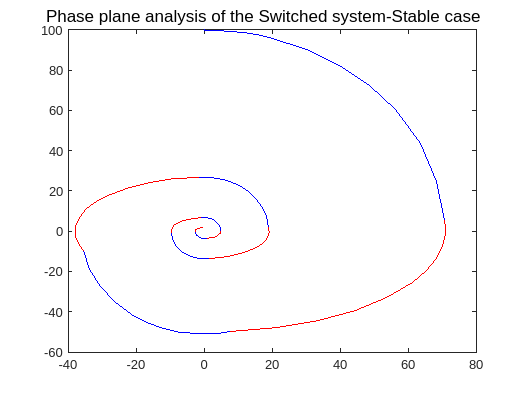

clc
clear
close
tspan = [0 50];
x_0=[0,100];
phase_plane=[];
f1=@(t,x) [-eps*x(1)+x(2);-2*x(1)-eps*x(2)];
f2=@(t,x) [-eps*x(1)+2*x(2);-x(1)-eps*x(2)];
[t,x] = ode45(f1,tspan, x_0);
index = find(x(:,2) < 0, 1)-1;
figure
sgtitle('Phase plane analysis of the Switched system-Stable case')
xlabel('x1')
ylabel('x2')
plot(x(1:index,1),x(1:index,2),'b')
hold on
[t,x] = ode45(f2,tspan, x(index,:));
index = find(x(:,1) < 0, 1)-1;
plot(x(1:index,1),x(1:index,2),'r')
hold on
[t,x] = ode45(f1,tspan, x(index,:));
index = find(x(:,2) > 0, 1)-1;
plot(x(1:index,1),x(1:index,2),'b')
hold on
[t,x] = ode45(f2,tspan, x(index,:));
index = find(x(:,1) > 0, 1)-1;
plot(x(1:index,1),x(1:index,2),'r')
hold on
[t,x] = ode45(f1,tspan, x(index,:));
index = find(x(:,2) < 0, 1)-1;
plot(x(1:index,1),x(1:index,2),'b')
hold on
[t,x] = ode45(f2,tspan, x(index,:));
index = find(x(:,1) < 0, 1)-1;
plot(x(1:index,1),x(1:index,2),'r')
hold on
[t,x] = ode45(f1,tspan, x(index,:));
index = find(x(:,2) > 0, 1)-1;
plot(x(1:index,1),x(1:index,2),'b')
hold on
[t,x] = ode45(f2,tspan, x(index,:));
index = find(x(:,1) > 0, 1)-1;
plot(x(1:index,1),x(1:index,2),'r')
hold on
[t,x] = ode45(f1,tspan, x(index,:));
index = find(x(:,2) < 0, 1)-1;
plot(x(1:index,1),x(1:index,2),'b')
hold on
[t,x] = ode45(f2,tspan, x(index,:));
index = find(x(:,1) < 0, 1)-1;
plot(x(1:index,1),x(1:index,2),'r')
hold on
[t,x] = ode45(f1,tspan, x(index,:));
index = find(x(:,2) > 0, 1)-1;
plot(x(1:index,1),x(1:index,2),'b')
hold on
[t,x] = ode45(f2,tspan, x(index,:));
index = find(x(:,1) > 0, 1)-1;
plot(x(1:index,1),x(1:index,2),'r')
hold on

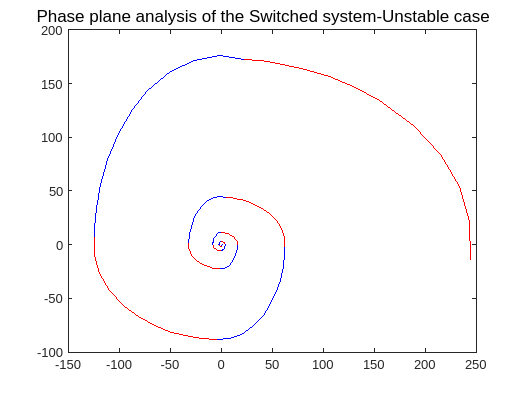

clc
clear
close
tspan = [0 50];
x_0=[1,0];
phase_plane=[];
f1=@(t,x) [-eps*x(1)+x(2);-2*x(1)-eps*x(2)];
f2=@(t,x) [-eps*x(1)+2*x(2);-x(1)-eps*x(2)];
[t,x] = ode45(f1,tspan, x_0);
index = find(x(:,1) < 0, 1)-1;
figure
sgtitle('Phase plane analysis of the Switched system-Unstable case')
xlabel('x1')
ylabel('x2')
plot(x(1:index,1),x(1:index,2),'b')
hold on
[t,x] = ode45(f2,tspan, x(index,:));
index = find(x(:,2) > 0, 1);
plot(x(1:index,1),x(1:index,2),'r')
hold on
[t,x] = ode45(f1,tspan, x(index,:));
index = find(x(:,1) > 0, 1);
plot(x(1:index,1),x(1:index,2),'b')
hold on
[t,x] = ode45(f2,tspan, x(index,:));
index = find(x(:,2) < 0, 1);
plot(x(1:index,1),x(1:index,2),'r')
hold on
[t,x] = ode45(f1,tspan, x(index,:));
index = find(x(:,1) < 0, 1);
plot(x(1:index,1),x(1:index,2),'b')
hold on
[t,x] = ode45(f2,tspan, x(index,:));
index = find(x(:,2) > 0, 1);
plot(x(1:index,1),x(1:index,2),'r')
hold on
[t,x] = ode45(f1,tspan, x(index,:));
index = find(x(:,1) > 0, 1);
plot(x(1:index,1),x(1:index,2),'b')
hold on
[t,x] = ode45(f2,tspan, x(index,:));
index = find(x(:,2) < 0, 1);
plot(x(1:index,1),x(1:index,2),'r')
hold on
[t,x] = ode45(f1,tspan, x(index,:));
index = find(x(:,1) < 0, 1);
plot(x(1:index,1),x(1:index,2),'b')
hold on
[t,x] = ode45(f2,tspan, x(index,:));
index = find(x(:,2) > 0, 1);
plot(x(1:index,1),x(1:index,2),'r')
hold on
[t,x] = ode45(f1,tspan, x(index,:));
index = find(x(:,1) > 0, 1);
plot(x(1:index,1),x(1:index,2),'b')
hold on
[t,x] = ode45(f2,tspan, x(index,:));
index = find(x(:,2) < 0, 1);
plot(x(1:index,1),x(1:index,2),'r')
hold on
[t,x] = ode45(f1,tspan, x(index,:));
index = find(x(:,1) < 0, 1);
plot(x(1:index,1),x(1:index,2),'b')
hold on
[t,x] = ode45(f2,tspan, x(index,:));
index = find(x(:,2) > 0, 1);
plot(x(1:index,1),x(1:index,2),'r')
hold on
[t,x] = ode45(f1,tspan, x(index,:));
index = find(x(:,1) > 0, 1);
plot(x(1:index,1),x(1:index,2),'b')
hold on
[t,x] = ode45(f2,tspan, x(index,:));
index = find(x(:,2) < 0, 1);
plot(x(1:index,1),x(1:index,2),'r')
hold on

**HOMOCLINIC ORBIT**

clc;
clear;
[x1,x2]=meshgrid(-5:0.25:5,-5:0.25:5);
mu1=1;
mu2=-0.755;
dx1=mu1*x1+x2;
dx2=(mu2-mu1)*x2+(x1*x1)-x1*x2;
figure;
quiver(x1,x2,dx1,dx2);
sgtitle('Phase plane analysis')
xlabel('x1')
ylabel('x2')
hold on
tspan=[0,10];
for i=1:5
    x0=ginput(1)
    [t,x]=ode45(@(t,x) odefun3(x),tspan,x0);
    plot(x(:,1),x(:,2),'r')
end

x0 =    -0.2221    0.1379


x0 =    -0.0209   -0.1073


x0 =     0.1131   -0.3985


x0 =     0.3561   -0.5977


Error using ginput
Interrupted by figure deletion

function dxdt=odefun1(x)
dxdt=zeros(2,1);
eps=1;
dxdt(1)=-eps*x(1)+x(2);
dxdt(2)=-2*x(1)-eps*x(2);
end

function dxdt=odefun2(x)
dxdt=zeros(2,1);
eps=1;
dxdt(1)=-eps*x(1)+2*x(2);
dxdt(2)=-x(1)-eps*x(2);
end

function dxdt=odefun3(x)
dxdt=zeros(2,1);
mu1=1;
mu2=-.755;
dxdt(1)=mu1*x(1)+x(2);
dxdt(2)=(mu2-mu1)*x(2)+(x(1)*x(1))-x(1)*x(2);
end